# **LAB7_spicyArduino**

------------------------------------------------------------------------------------------------------------------------------------------------------

Created: 7 May 2019

By: Samuel Bechara and Joshua Christopher

## Introduction

Monitoring temperatures is a critical part of many projects and their resulting products. For example, if your car starts to overheat it should shut off automatically. What would happen if the car wasn't monitoring the engine temperature and didn't shut off?

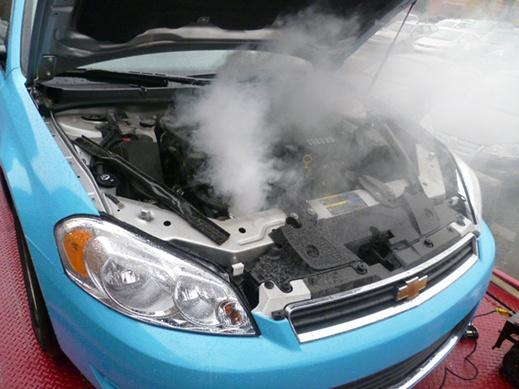

Thermometers are also used for less critical parts of a design. Power generation plants use thermometers to monitor their heat reservior, whether that is a coal fired furnace or a geothermal hot spot. This monitoring allows engineers to quickly identify if the power plant is operating out of spec and address any problems that arise. 

This lab will reinforce the concepts we have been learning about plotting and array mathematics. Insert brief review of those concepts here.

We will break the lab into two components:

- Hardware Setup

- MATLAB Programming

## 1) Hardware Setup

Obviously, we are going to have to hook up the temperature sensor to the Arduino in order to read the values. We are going to do that with a breadboard and some jumper wires.

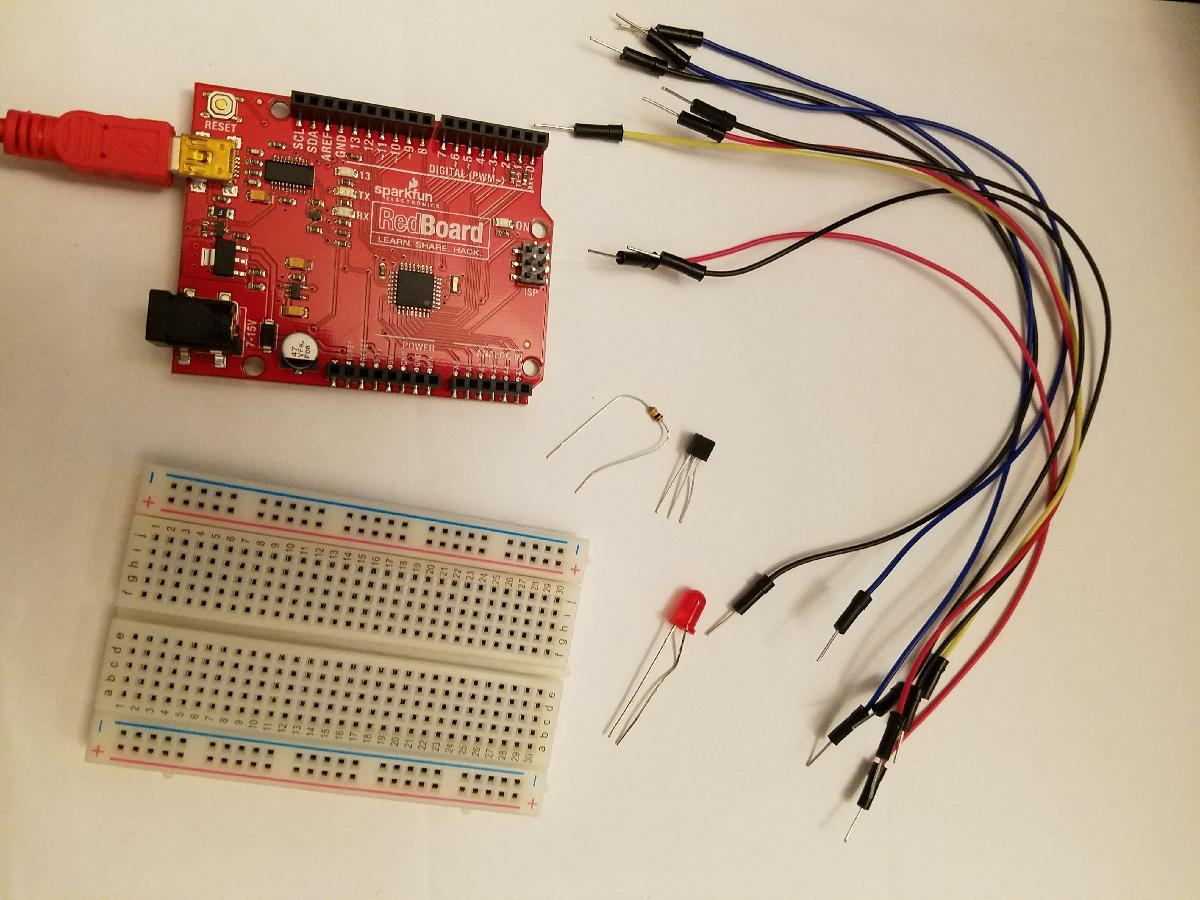

For this lab you will also need an LED (any color, I chose red) and a resistor of at least 300 ohm (I'm using a 10K ohm resistor, which is overkill but perfectly fine). You will need a total of 8 jumpers.

In order to make this all work you need to know a couple of things about breadboards. Although it is out of the scope of this lab, it is a good idea for you to get a basic knowledge of how electricity works and the physical properties that govern the movement of charge through wires. http://www.instructables.com/id/Basic-Electronics/ is a great website that can help you get started.

### Breadboards

The three main concepts that you need for today are to understand that:

1) In order to work, circuits need to be powered

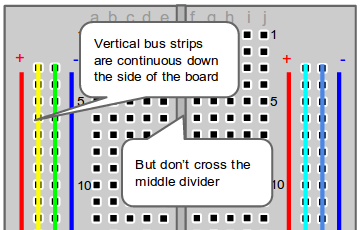

Just like water won't move unless it is on a hill, charge won't move unless there is a potential difference. Our ardunio has the ability to power devices that require both 3.3V and 5V sources.To do this, we will use the vertical bus strips on the breadboard to easily connect to our power source. Since our heart rate module requires a 3.3V source, we will use one jumper wire to connect the 3.3V power source on the arduino to the + vertical bus and another jumper wire to connect ground from the ardunio (GND) to the – vertical bus. This will provide the power we need for our circuit.

In the example we will do today, this is technically unnecessary, we could connect directly to the ardunio to the sensor with one jumper wire. But it is good form if you decide to add more sensors in the future!	

2) In order to work, circuits need to be closed

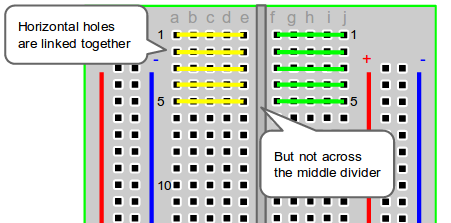

The jumper wires and the breadboard allow us to close circuits. The breadboard has plates that run along the numbered rows but do not cross the middle divider. This allows us to use jumper wires to make connections from the ardunio, to the heart rate sensor module, without directly connecting a wire to each.

If you are having a problem, it is likely that you have an open circuit.

3) Do not create a short circuit

DON’T DO THIS, but if you connect a wire directly from the positive to the negative side of a power supply, you’ll create what is called a short circuit. This is a very bad idea. If in doubt, ask if the connection you are making is a short circuit.

[Watch what happens when you create a short circuit!](https://www.youtube.com/watch?v=mqEaIdvxXYQ)

### About the TMP36 Temperature Sensor

The TMP36 temperature sensor is a low voltage, precision centigrade temperature sensor. It provides a voltage output that is linearlly proportional to the temperature. We can use it's voltage output and a little math, to get very accurate readings on ambient temperature. How did I know all that? I looked at the spec sheet. Take a look at the spec sheet and figure out which pins are labled what...

[specsheet link]

*Hint: Pictures are worth a thousand words, especially in spec sheets.*

### Connection Steps - Hardware

Choose a region on the breadboard to put your TMP 36 sensor. Remember, **you do not want to place it so that all of the connections are along the same row**, that would be a short circuit! **Make sure you understand how a breadboard works and what the pins on the TMP 36 sensor coorespond to.** In the figure below, the the sensor is placed at the top of the "A" column of the breadboard. Try putting yours somewhere else.

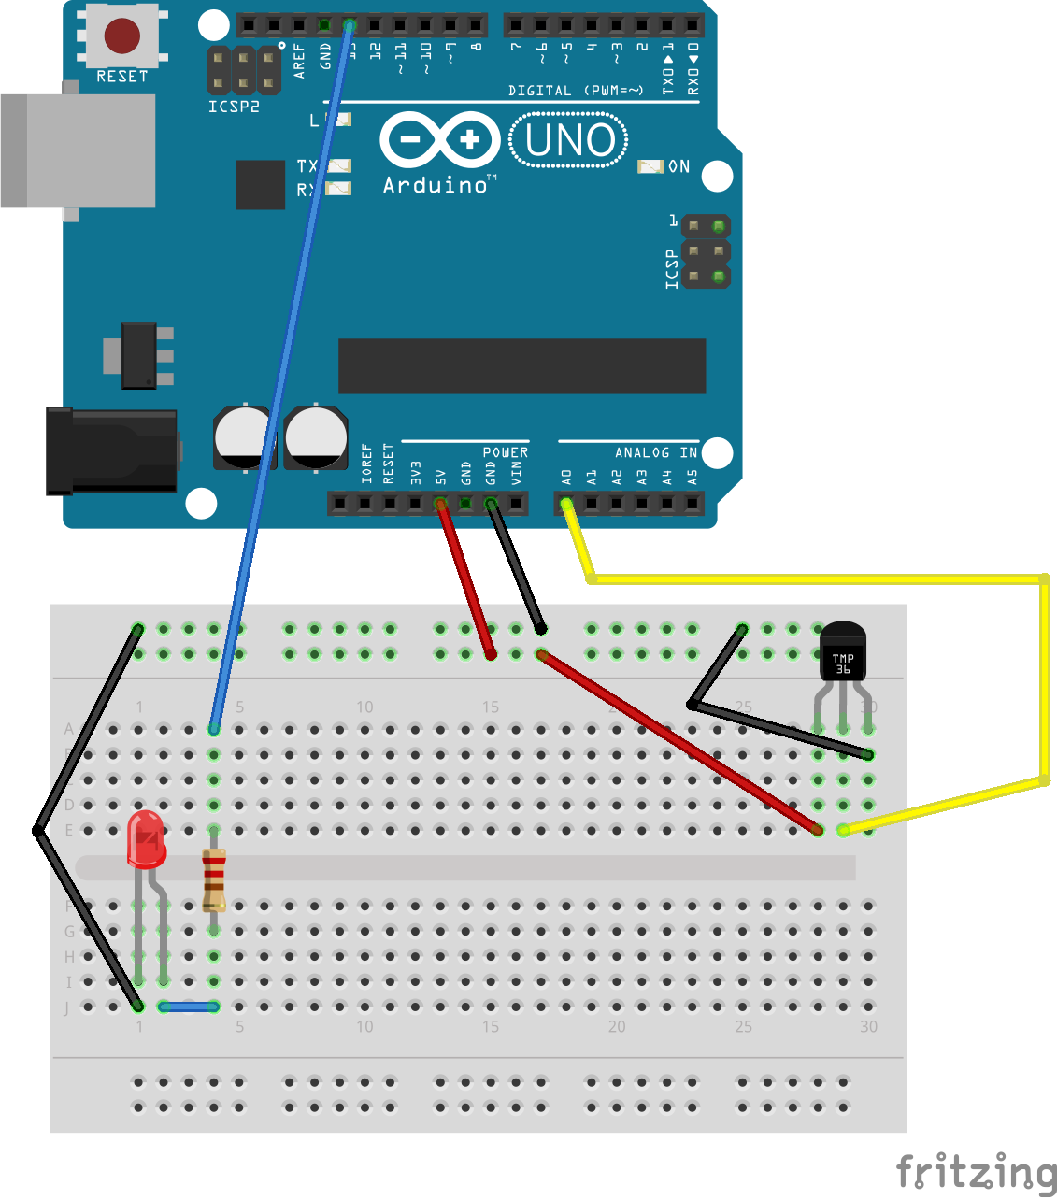

Remember, circuits need power! In this example we are going to use the vertical bus strips on the breadboard. Using a jumper wire, connect the (+) vertical bus strip on the breadboard to the 5V power source on the ardunio. Now the entire (+) column is connected to this source.

Similarly, use a jumper wire to connect the GND source on the ardunio to the (-) vertical bus strip on the breadboard. The (-) column is now grounded.

Using the spec sheet, determine which pin is the positive voltage input pin (+$V_s$), which pin is the ground (GND), and which pin is the output voltage ($V_{OUT}$). Very carefully read the spec on this! Which way are the diagrams oriented from the viewer's perspective? I highly recommend orientating your component the same way as the spec sheet when you figure out which pin is which. Think for a second: what would happen if you accidentally reversed the positive voltage pin and the ground?

Once you figure out which pin is which, start by using a jumper wire to connect the positive voltage pin to the (+) column of your breadboard. Use another jumper to connect the ground pin to the (-) column of your breadboard.

Use yet another jumper to connect the output voltage ($V_{OUT}$) pin of the thermometer to the A0 analog input pin on the Arduino. You could also hook it up to any other analog input pin on the Arduino, you will just have to be careful to use the right pin names later!

Our temperature sensor is now connected! We still need to hook up the LED though. Place the LED somewhere on your breadboard thats not in the same row as your temperature sensor. I placed my LED on nearly the entire opposite side of the breadboard from my temperature sensor. 

I will leave it up to you to figure out how to connect the rest of the LED as shown in the diagram above. Look at the spec sheet for your LED. Which lead is the negative side? Which is the positive side? Remember that you want the electricity to flow through the resistor, then through the LED. Don't short your resistor unless you want to melt your LED!

One more thing to note: you can (typically) use a common ground for all your components! Both your LED and your temperature sensor can connect to the same column on the breadboard which leads to the same ground pin on the Arduino.

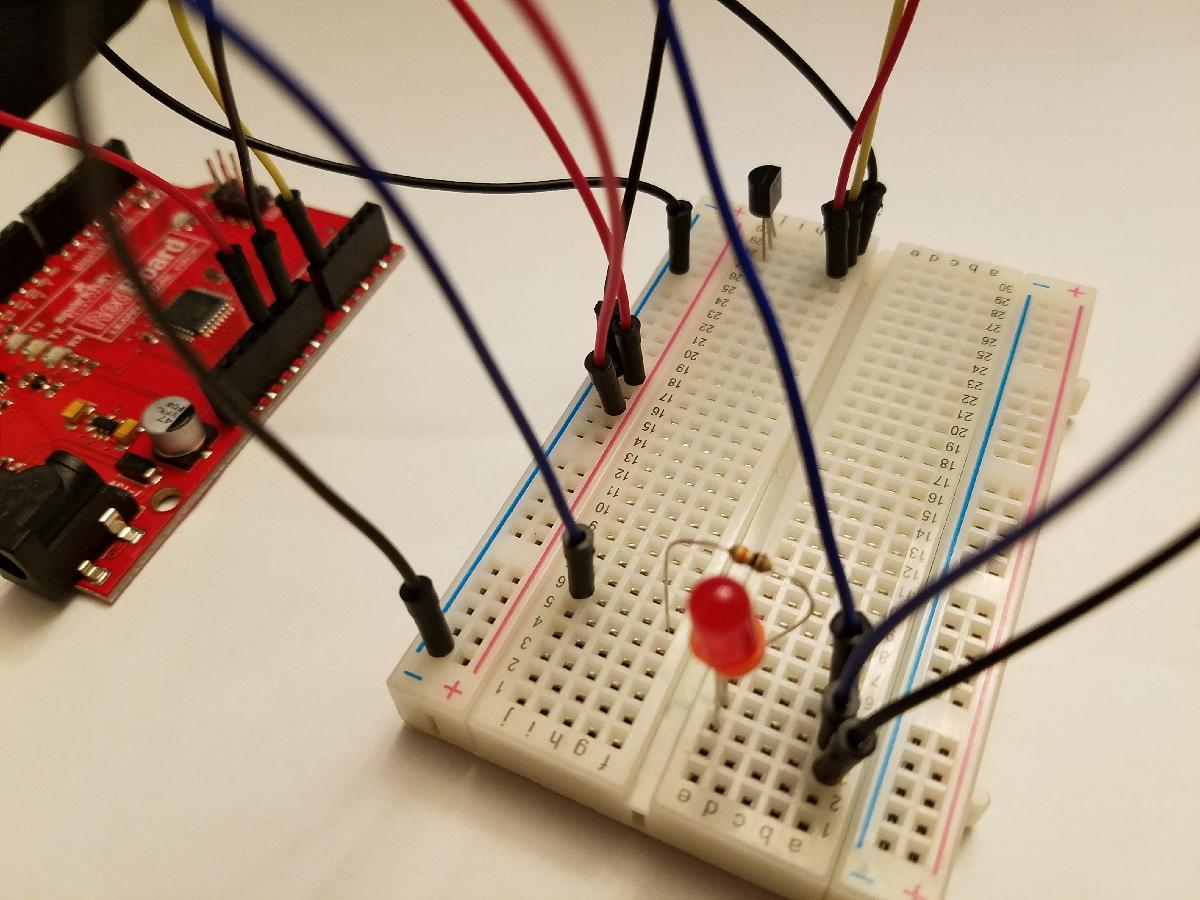

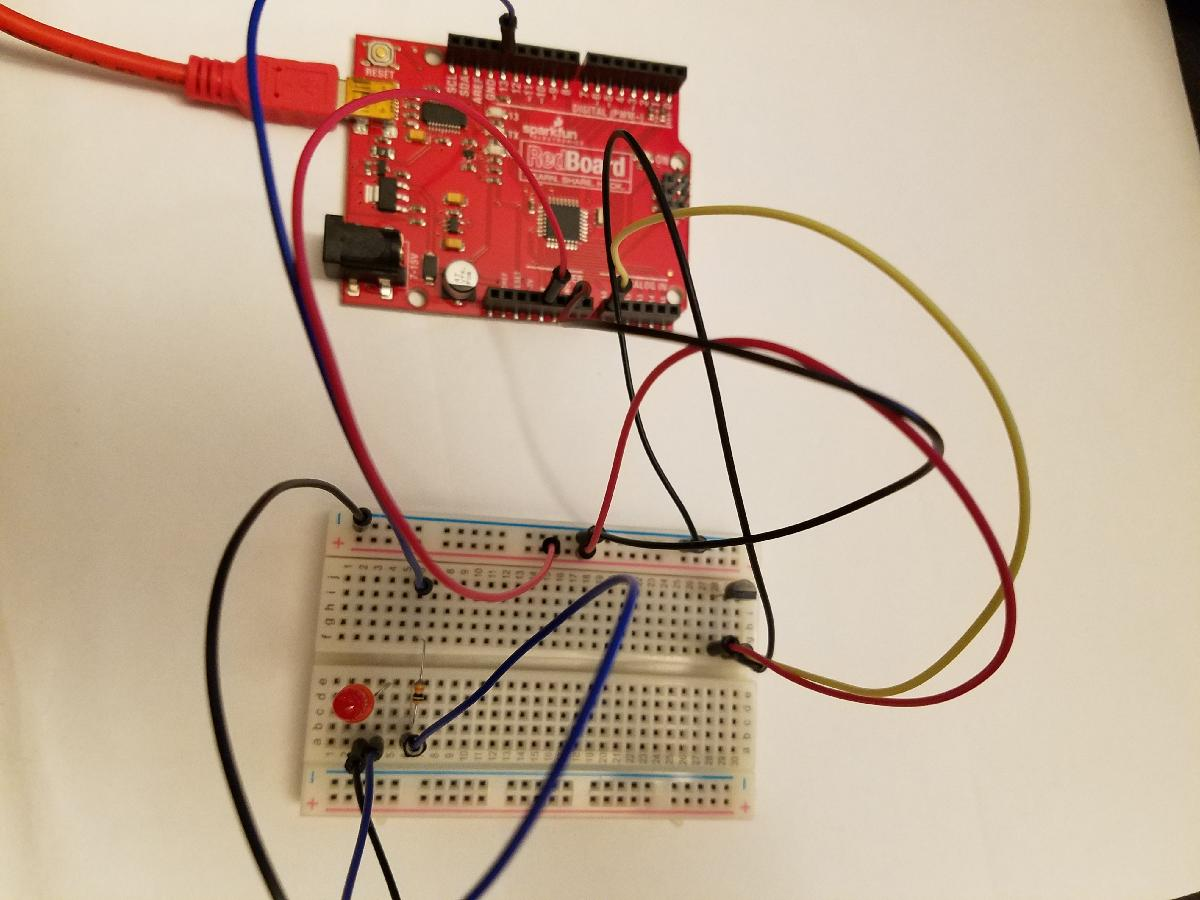

## 2) MATLAB Programming

Now comes the fun part, unzombie-ifying the setup. Right now everything should be connected correctly, but the arduino doesn't have a brain, it is still doing the exact same thing as last week... spooky! Let's give the arduino instructions, get some data, and use our knowledge of array mathematics and plotting to visualize the sensor data.

Below is a template of the code you need to collect temperature measurements from the Arduino. As written it will not work, you need to complete the Recall what you learned in last week's lab. What do you need to connect Matlab to the Arduino board? Remember how to tell the Arduino to turn on the onboard LED light?

Read through the following source code and ask yourself the following questions:

- What Arduino pins have I connected the various components (sensors, LEDs, etc.) to?

- How can I use the Command Window to test code or get sample data instantly (i.e. without having to run the script)?

- What kind of data am I trying to collect? Is it an integer? Is it a floating point value? Is it a string? How do I want to store this data?

- How can I make use of the data I collected? What is the goal I am trying to achieve with it?

We haven't talked about for loops yet, but from reading the code can you figure out what it does? Try copy and pasting the for loop into a new script or into the Command Window to test out the script and see what it does. In your test, remove the Arduino specific stuff and just play around with the disp() and pause() functions.

We also haven't discussed if statements yet. Again, from reading the code can you figure out how it works? The template below has an if statement with the conditional 

voltage(j) >= threshold

What does this conditional mean? What is the data type of what it returns? Try putting a similar conditional into the Command Window, for example, type in the two commands:

2 >= 4
5 >= 4

Which code in the if statement should be taken for those two conditionals?

There is one additional Arduino command that you need to complete run the code: **readVoltage(arduino, pin);**. This command does exactly what it sounds like: it reads the voltage from the given pin on the arduino you give it. One example of its usage is shown in the template below, but you will need to make more use of it.

What you need to figure out next:

- You are currently reading voltage from the Arduino but need to convert that to temperature (in degrees Celsius). Look at the spec sheet (specifically page 5). You have a TMP36. On the chart for output voltage vs temperature you see that there is a linear relation between voltage and temperature. At 0°C the output voltage is 0.5V, and at 50°C the output voltage is 1.0V. Figure out the equation to convert from voltage to degrees Celsius. Then convert your voltage array into a temperature array. You can do this easily and without a for loop by using array operations.

- Create an array containing the time that each voltage measurement was taken. This will make up the x-axis of your chart. You can treat the time to run all the commands as negligible so that the times of the measurements are after every pause. Recall your assignments from last week's lab for how you can create such an array.

- Use Matlab's plotting capabilities to plot the time vs temperature.

- Try converting from Celsius to Fahrenheit.

## 3) Now lets have some fun!

Now that you have a working temperature sensor, lets do some fun stuff with it! Do the following things:

- Change the number of data points. What happens?

- Set the number of data points to something a bit bigger, like 30. While your Arduino is collecting the data, put your fingers around the temperature sensor. Don't pull it off the breadboard! Or do... what happens then? Why? While actually leaving the sensor in though, keep your fingers around the sensor and see if you can make the temperatures increase over time.

- Find a partner or two with one laptop and Arduino between the set of you. Increase the number of data points to something even bigger, like 60 or 120. CAREFULLY, without dropping your laptop or Arduino, walk outside and watch the temperature drop (or increase? I don't know what the temperature will be the day of your lab). Also don't do this if it is raining outside!

- Figure out how to plot all of this data at the same time using subplots and the "hold on" command.

- What is the hottest you can get the temperature sensor? What about the coldest?

- Typically when you turn in assignments, you can't give a Matlab script to your professor. They want to see the data as a picture in a report or in a slideshow. See if you can save your plots as a picture (a jpg or png file type usually works).

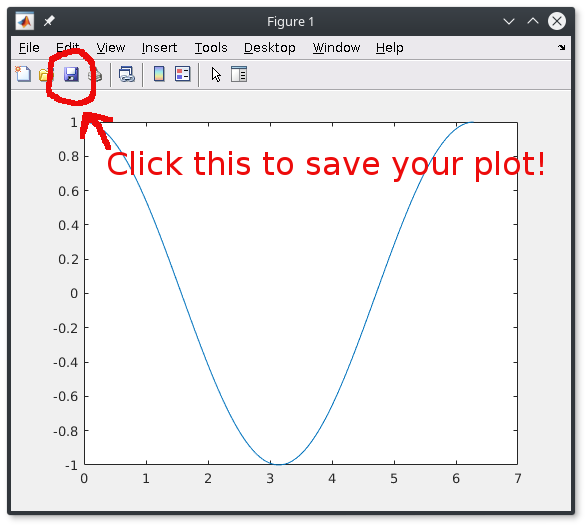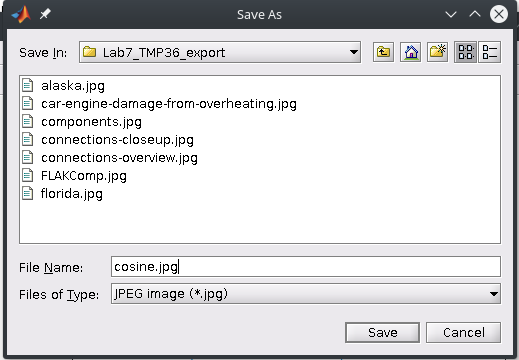

# Why is it snowing in October?!?

If you are new to Colorado, you may have been asking yourself that, unless you are from somewhere like Alaska. Welcome to the state with the biggest temperature swings I have ever experienced! 

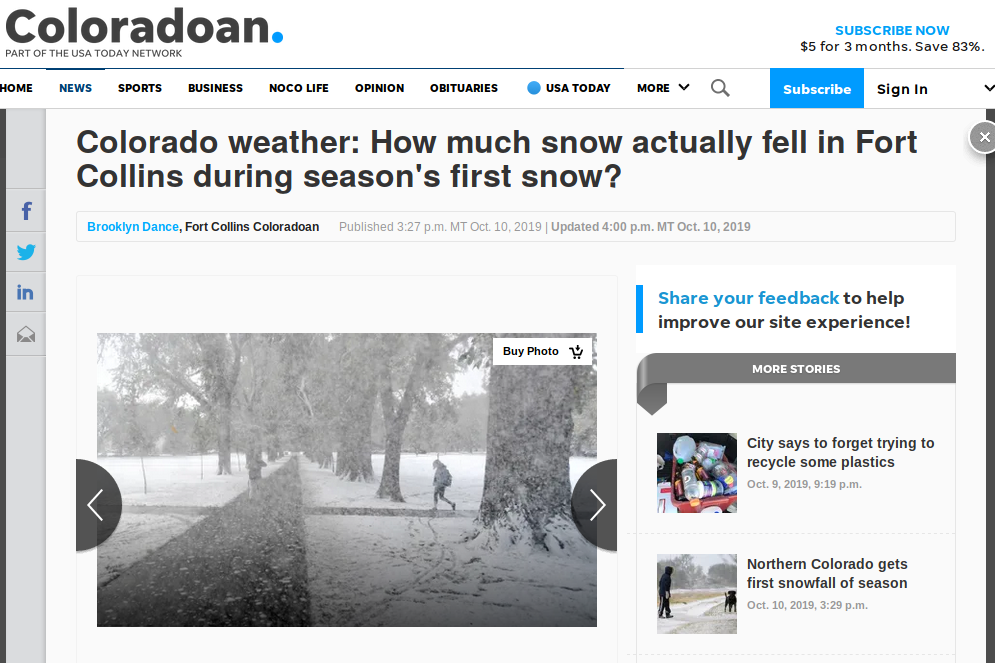

The Coloradoan website is ugly and slow. Don't @ me.

It would have been really cool to capture that temperature swing with your fancy new Arduino temperature sensor. Fortunately for you, I have a time machine called *The Internet*. I went and got the voltage readings for August 9th, 10th, and 11th as if you had left your Arduino outside in that messy weather. Just like last week, you need the provided Matlab file. This week it is called getVoltages.m and outputs two arrays: the date-time and the Arduino's voltage:

[date_times, voltages] = getVoltages();

You may have noticed that I am careful not to name thiings 'datetime'. That is because datetime() is a Matlab function that creates date-time objects, so you probably don't want to name your variable that unless you like confusing Matlab. Go ahead and read the help for it by typing in *help datetime*. 

Just like earlier in the lab, you will need to convert your voltages to something humans can understand, like Kelvins. Everyone has an intuitive sense of Kelvins, right?

If you guessed that we're going to plot this data, you guessed right! Write a MATLAB **script** and submit it online to Matlab Grader that meets the following requirements:

- A variable called **date_times** that is an array containing the date-times info from the getSteamTable() function.

- A variable called **voltages **that is an array containing the voltage info from the getSteamTable() function.

- A variable called **tempsC **that is an array containing the temperatures in Celsius

- A variable called **tempsF **that is an array containing the temperatures in Fahrenheit

- Make a plot of the temperature in Fahrenheit over time. Look at that temperature just plummet in the evening of the 9th!

- Make sure your plot has all the usual elements of what makes a good plot: title, axis labels, grid lines, etc.

- Since you are plotting experimental data and not continuous data, what type of plot should it be? Make sure you choose the correct style! Read about how to set the line type, plot symbols, and colors by typing *help* *plot *into your command window.

# How was the rest of the country?

Well... I'm not going to get the temperatures for the entire country, but lets take a look at some polar opposites: Fairbanks, Alaska and Miami, Florida! 

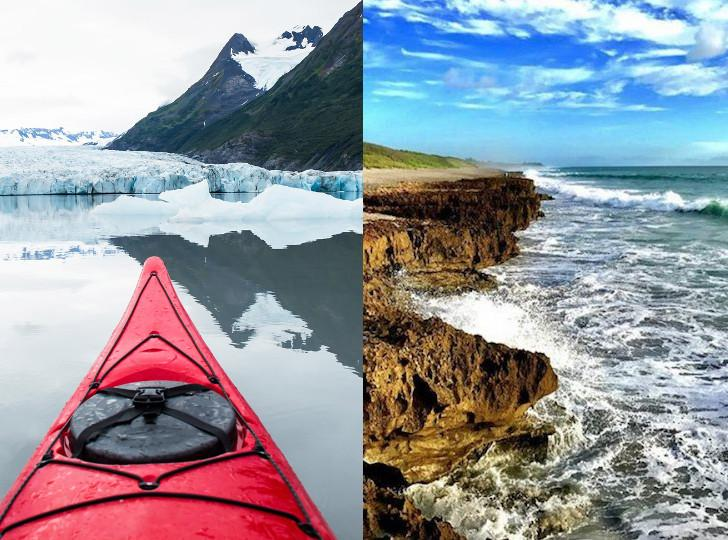

I have no idea where these pictures were actually taken, probably not Fairbanks or Miami though.

You have two more files with Matlab data that we haven't used yet: getFairbanksTemperatures.m and getMiamiTemperatures.m. Hopefully it is pretty obvious what they do just from the names. They contain the temperature in Fahrenheit for each place! You get the data from them similarily to how you get the voltages, except this time they contain nothing but temperatures (no date_times)!

miamiTemperatures = getMiamiTemperatures();

I made this less tedious for you by providing the temperatures at the same date_times as your votage readings. Using knowledge from class and the book readings, plot the temperatures for all three on the same chart. In fact, lets go one step further and also plot a horizontal line at the freezing point for water. Think of an easy way to create an array containing the freezing point that you can plot. What are some functions that you learned that will help with this task?

Write a MATLAB **script** and submit it online to Matlab Grader that meets the following requirements:

- A variable called **date_times** that is an array containing the date-times info from the getSteamTable() function.

- A variable called **tempsF **that is an array containing the Fort Collins/Arduino temperatures in Fahrenheit (same array as the last question)

- A variable called **miamiTemperatures** that is an array containing the Miami temperatures in Fahrenheit

- A variable called **fairbanksTemperatures **that is an array containing the Fairbanks temperatures in Fahrenheit

- A variable called **freezing **that is an array containing the freezing point of water (assuming constant pressure and volume etc, make it easy!).

- Make a chart that has all three temperatures plotted over time on the same axis. You should see the temperature lines crossing each other.

- Make sure your plot has all the usual elements of what makes a good plot: title, axis labels, grid lines, etc.

- Ensure you have the correct line or symbols for your plots.

# Would a polar bear be happier in Fort Collins?

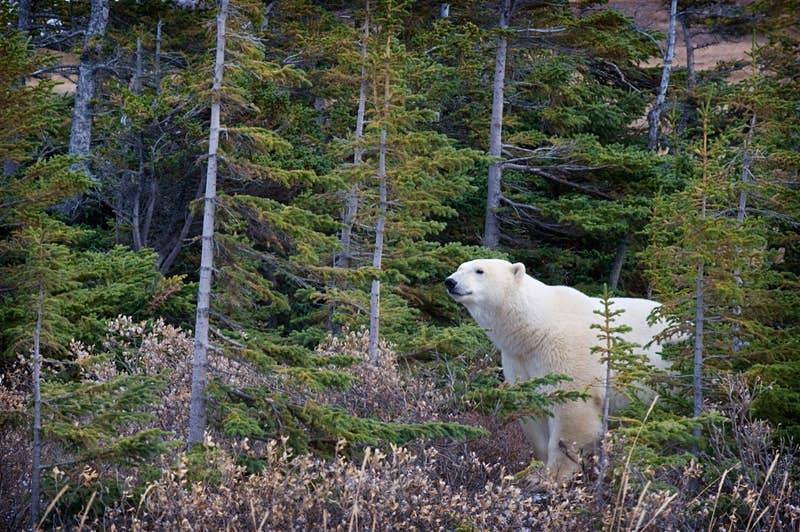

We can assume they wouldn't be happy in Miami.

Lets do one last exercise with the temperature data you have from Fort Collins, Fairbanks, and Miami. This time, instead of plotting them all on the same axis lets plot them all in different subplots. Make your subplots so that you have 1 row with three columns. In the left most subplot, plot the temperature over time from Fairbanks. In the middle subplot, plot the temperature from Fort Collins. In the last column, plot the temperature from Miami. Use units of Fahrenheit for all three plots. Afterwards, find the min and max for all three cities using Matlab's built in functions.

Write a MATLAB **script** and submit it online to Matlab Grader that meets the following requirements:

- A variable called **date_times** that is an array containing the date-times info from the getSteamTable() function.

- A variable called **tempsF **that is an array containing the Fort Collins/Arduino temperatures in Fahrenheit (same array as the last question)

- A variable called **miamiTemperatures** that is an array containing the Miami temperatures in Fahrenheit

- A variable called **fairbanksTemperatures **that is an array containing the Fairbanks temperatures in Fahrenheit

- A variable called **minTemps **that is an array containing the minimum temperature for all three cities so that Fairbanks is the first element, Fort Collins the second element, and Miami the last element. Try to use array concatenation to create the **minTemps **array in one line!

- A variable called **maxTemps **that is an array containing the maximum temperature for all three cities so that Fairbanks is the first element, Fort Collins the second element, and Miami the last element. Again, you should be able to make this one line.

- A variable called **stdTemps **that is an array containing the standard deviation for all three cities. Use the same city order as last time.You should also be able to make this one line via array concatenation.

- Make a chart that has all three temperatures plotted in the subplots as specified above.

- Make sure your plot has all the usual elements of what makes a good plot: title, axis labels, grid lines, etc.

- Ensure you have the correct line or symbols for your plots.